Reto 1: Parte 3

Profundización II: Electromedicina

Restauración de imágenes de leucocitos de un canino.

Leandro Ramos - 219160260

Brandon Rosero - 219160289

Primero que todo se inicializa el codigo haciendo una limpieza total (variables, gráficas y consola).

clc; clear variables; close all

Se procede a añadir carpetas a la ruta de búsqueda con la función "addpatch", con el fin de cargar cualquier función que se utilice.

addpath 'C:\Users\BASTI\OneDrive\Escritorio\finales'

Leer una imágen seleccionada del banco banco de imagenes con la función "leerRx(x,y)"  y el ciclo "for i=1:z" de la siguiente manera:

- Modificando la variable "y" en un rango entre 1 o 2, se obtiene el banco de imágenes de pneumonia y sanos respectivamente.

- Modificando la variable "z" en el ciclo for continuo a la función "leerRx", se puede obtener una imágen diferente del banco seleccionado (pneumonia o sanos).

a = leerRx(26,1); %almacena todas las imagnes de la lista 1 o 2
for i = 1:4
I = a{i};
end

Una vez seleccionada la imágen a trabajar, se procede a graficarla, con el fin de observar lo que se tiene presentemente y así poder observar los futuros cambios que se obtendrán.

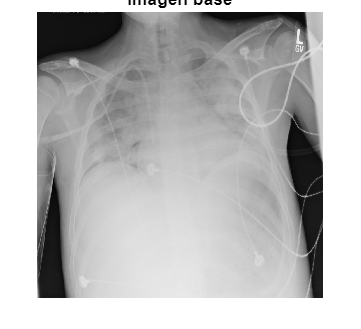

figure
imshow(I);
title("Imagen base");

I = rgb2gray(I);

Se procede a seleccionar una regíon uniforme de la imagen para identificar un patrón de ruido con su respectiva pdf.

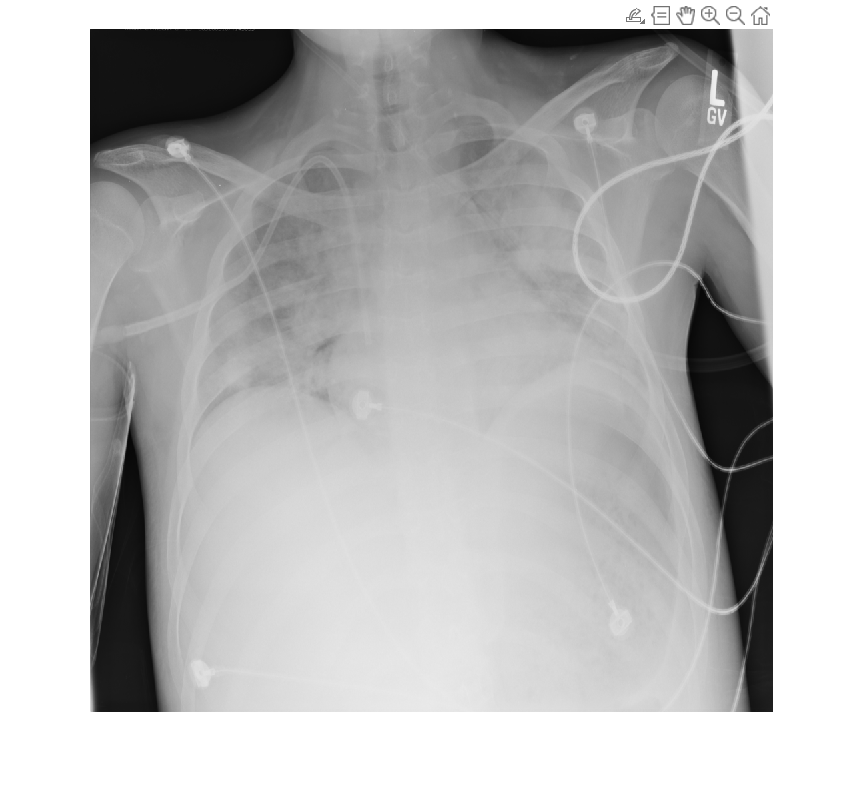

Ir = imcrop(I); %seleccionar region uniforme

Se procede a obtener el tamaño correspondiente al fragmento de región seleccionado.

[M , N] = size(Ir);

Se obtiene el histograma y se lo divide entre el área total de pixeles con el fin de normalizar entre 0 y 1 (PDF).

p = imhist(Ir)/(M*N);

Se crea un vector en el eje x del tamaño 256 con el fin de graficar el histograma.

L = 0:255;

Se procede a graficar el histograma y observar algún patrón de tendencia posible.

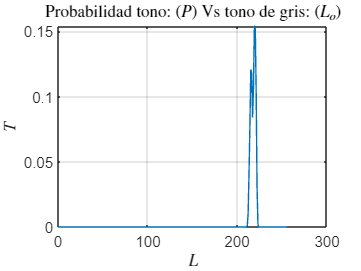

figure
plot(L,p);
grid("on");
title("Probabilidad tono: $(P)$ Vs tono de gris: $(L_o)$",LineWidth = 3,Interpreter="latex");
ylabel("$T$",LineWidth = 3,Interpreter="latex");
xlabel("$L$",LineWidth = 3,Interpreter="latex");

Se pudo observar que el patrón tiene una tendencia un tanto paecido a una gaussiana, por lo que se podria ajustar una curva de dicho tipo al historama.

Con la informacion almacenada en las varialbes P y L se realiza una estimacion gausiana usando la app de matlaba "Curve Fitter".

Codigo generado por la app Curve Fitter. devido a las variables iniciales es necesario seleccionar un recuadro negro en la imagen.

[xData, yData] = prepareCurveData( L, p );

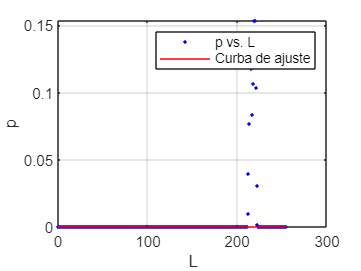


% Configure el tipo de ajuste y las opciones.
ft = fittype( 'gauss1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf -Inf 0];
opts.StartPoint = [0.688423645320197 7 0.399916626116222];

% Ajustar el modelo a los datos.
[fitresult, gof] = fit( xData, yData, ft, opts );

% Ajuste de la trama con los datos.
figure( 'Name', 'untitled fit 1' );
h = plot( fitresult, xData, yData );
legend( h, 'p vs. L', 'Curba de ajuste', 'Location', 'NorthEast', 'Interpreter', 'none' );
xlabel( 'L', 'Interpreter', 'none' );
ylabel( 'p', 'Interpreter', 'none' );
grid on

disp(fitresult);

     General model Gauss1:
     fitresult(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =          -0  (-0.04173, 0.04173)
       b1 =           7
       c1 =      0.3999


Ahora bien, con la curva de ajuste creada, se procede a hacer un análisis en la frecuencia de la imágen.

Se convierte la imágen a valores numéricos:

I = double(I);

Se aplica la transformada de fourier en 2D a la imágen y se obtiene su parte real.

El algorítmo que define la transformada rápida de fourier es el siguiente $[1]$:

                             $X[k]=\sum_{n=0}^{N-1}X_0[n]\, e^{-\frac{2\pi i}{N} kn}.

$                         (1)

donde $X_0[n]$ es una señal discreta en el tiempo.

If = fft2(I); %trasformada de fourier 2d de imagen.
Ifa = abs(If);

Se grafica el espectro de Fourier en escala logarítmica para observar el comportamiento del espectro:

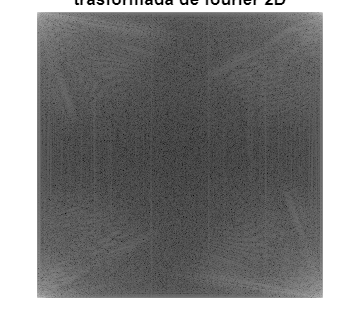

figure
imshow((log(1+(Ifa))),[]);
title("trasformada de fourier 2D");

Con el espectro de fourier creado, se procede a crear un filtro notch que se encargue de extraer las componentes verticales del espectro:

[~,~,H] = masnotch(I,50,25); % forma del filtro

limite = 0.9974

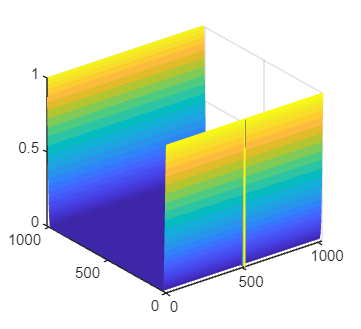

H = fftshift(H);
mesh(H);

Con el fiitro creado se procede a hacer una multiplicación entre el espectro de la imágen y el filtro, lo que equivale a una convolución en el dominio del tiempo:

In = If.*H; % aplicacion del filtro en frecuencia

Se procede a obtener la parte real de la inversa del espectro de fourier de la operación realizada anteriormente y se muestra lo obtenido:

In = real(ifft2(In));

Matemáticamente hablando, la transformada inversa de fourier es la siguiente [1]:

                           $X_0[n]=\frac{1}{N} \sum_{n=0}^{N-1}X[k]\, e^{\frac{2\pi i}{N} kn}.$                  (2)

Ahora bien, se procede a restar el resultado obtenido a la imagen original de manera óptima, es decir, por una resta de vecindarios acompañado por el producto de la función de ponderación. La función "notch_optimo()" se encarga de aplicar la resta de vecindarios".

In = notch_optimo(I,In,1); % funcion de notch optimo

Lal función de ponderación definida en clase se calcula de la siguiente forma:

                              $\frac{\overline{𝑔(𝑥, 𝑦)𝜂(𝑥, 𝑦)}-\overline{g}(x,y) \overline{𝜂}(x,y)}{\overline{𝜂2(x,y)} - \overline{𝜂(x,y)} ^{2} }$              (3)

Con el fin de repartir la escala de gris una vez aplicado el filtro, se realiza una ecualizacion con maching de histograma con la funcion ecualizarmach; esto con el fin de obeter información de la imagen, seguido se aplica un filtro pasa altas con frecuencia de corte en 8 y asi obtener la figura.

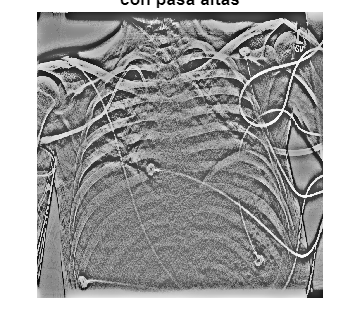

In2 = ecualizarmach(In); % maching
In2 = ihig(In2,8); % filtro pasa altas
figure
imshow(In2,[]);
title("con pasa altas");

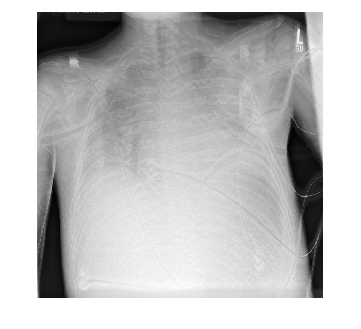

In2 = notch_optimo(I,In2,1);
figure
imshow(In2,[]);

Aunque la imágen obtenida no contiene el patrón de interferencia establecido (Costillas), lo obtenido en sí es un poco difuso con respecto a su contraste.

Para realizar una ecualizacion por matching y asi dejar mas visible la imagen es necesario crear una funcion Td que represente el histograma acomulado que se quiera en la imagen.

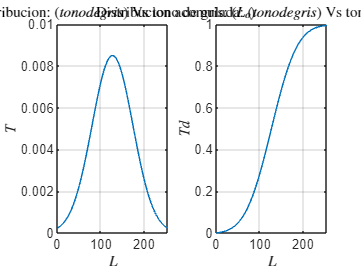

gaus = normpdf(L,127.5,47);
Td = cumsum(gaus);
figure
subplot(1,2,1)
plot(L,gaus);
grid("on");
title("Distribucion: $(tono de gris)$ Vs tono de gris: $(L_o)$",LineWidth = 3,Interpreter="latex");
ylabel("$T$",LineWidth = 3,Interpreter="latex");
xlabel("$L$",LineWidth = 3,Interpreter="latex");
subplot(1,2,2)
plot(L,Td);
grid("on");
title("Distribucion acomulada: $(tono de gris)$ Vs tono de gris: $(L_o)$",LineWidth = 3,Interpreter="latex");
ylabel("$Td$",LineWidth = 3,Interpreter="latex");
xlabel("$L$",LineWidth = 3,Interpreter="latex");

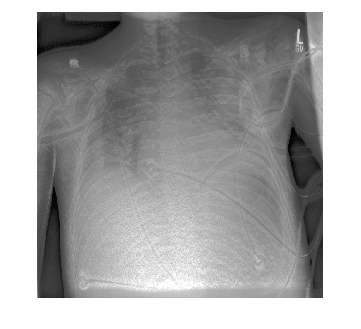

In3 = ecualizarf(In2,Td);
figure
imshow(In3);

Con el fin de obtener una imagen mas clara se realiza un maching con una funcion exponencial.

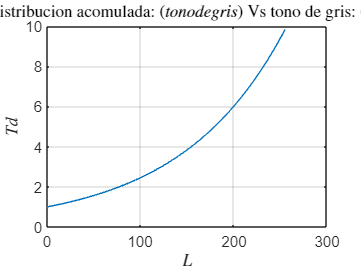

Td = 1.009.^L; % forma del histograma acomulado deceado
figure
plot(L,Td);
grid("on");
title("Distribucion acomulada: $(tono de gris)$ Vs tono de gris: $(L_o)$",LineWidth = 3,Interpreter="latex");
ylabel("$Td$",LineWidth = 3,Interpreter="latex");
xlabel("$L$",LineWidth = 3,Interpreter="latex");

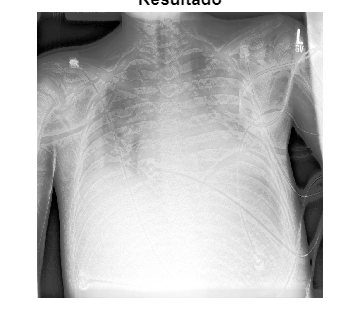

In3 = ecualizarf(In2,Td);
figure
imshow(In3);
title("Resultado")

Referencias

[1]. Ramírez Cortés, Juan Manuel; Gómez Gil, María del Pilar; Báez López, David (marzo-abril de 1998). "El algoritmo de la Transformada Rápida de Fourier y su controvertido origen". *Ciencia y Desarrollo* **24** (139): 70-77. 

[2] Rafael C. Gonzalez y Richard E. Woods (2018) Digital Image Processing, Pearson, 4th ed, University of Tennessee.

[3] Rangaraj M. Rangayyan (2015) Biomedical Signal Analysis, The Institute of Electrical and Electronics Engineers, Inc., 2nd ed.